**Load paths**

addpath(genpath(pwd));

load forecastingbattle.mat

T = datetime(2021,01,01,0:13679,0,0)';
Q = InflowData2;
K = (1:size(Q,1))'

K =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10



SQ = sum(Q,2)

SQ =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


size(SQ)

ans =        13680           1


size(T)

ans =        13680           1


Plot

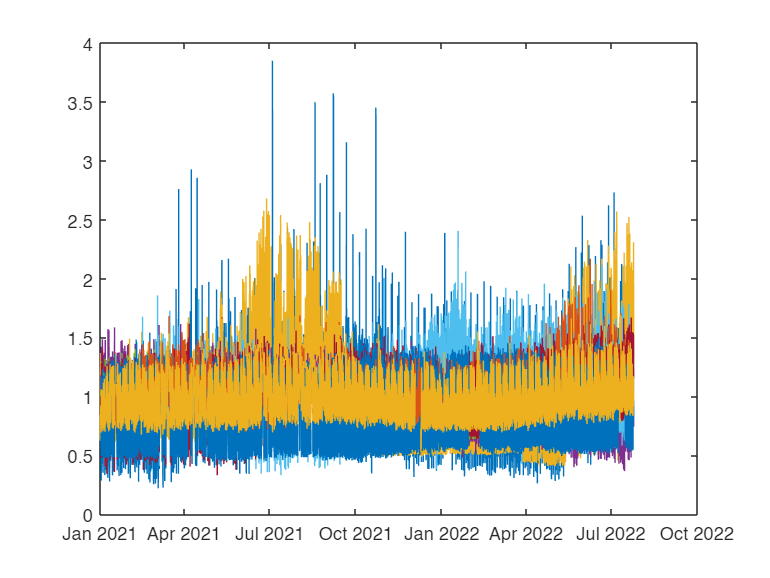

figure
plot(T, Q./nanmedian(Q))

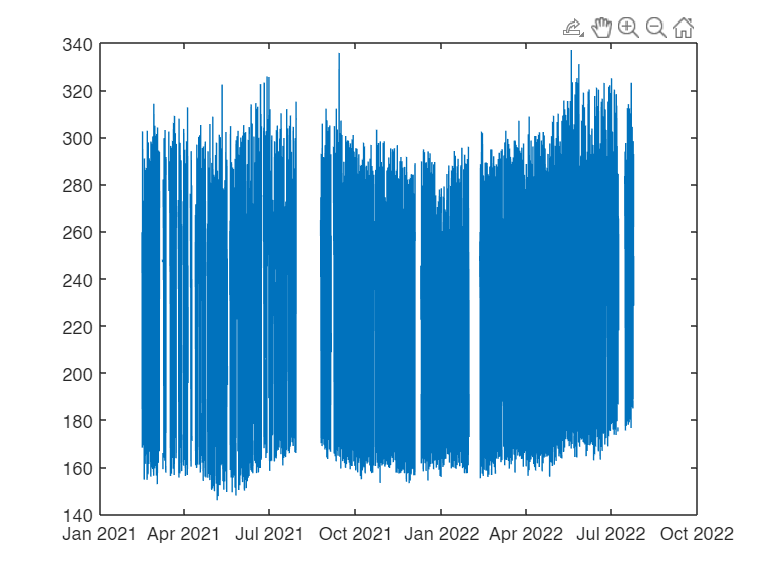


figure
plot(T,SQ)

incl = ~isnan(SQ)

incl = 13680×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


KD = K(incl);
FD = SQ(incl)/nanmedian(SQ);

Seasonality term

FourierTerms = 2;
w = 2 * pi/(365*24);
KDW = K(incl);
FDW = SQ(incl);

A1 = [ones(length(KDW),1) cos((1:FourierTerms)'*w*(KDW'))' sin((1:FourierTerms)'*w*(KDW'))'];
rcoef = A1\FDW

rcoef =   214.5622
  -94.1876
   99.2587
  166.4264
  -39.7641



K2 = (1:(2*size(Q,1)))'

K2 =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


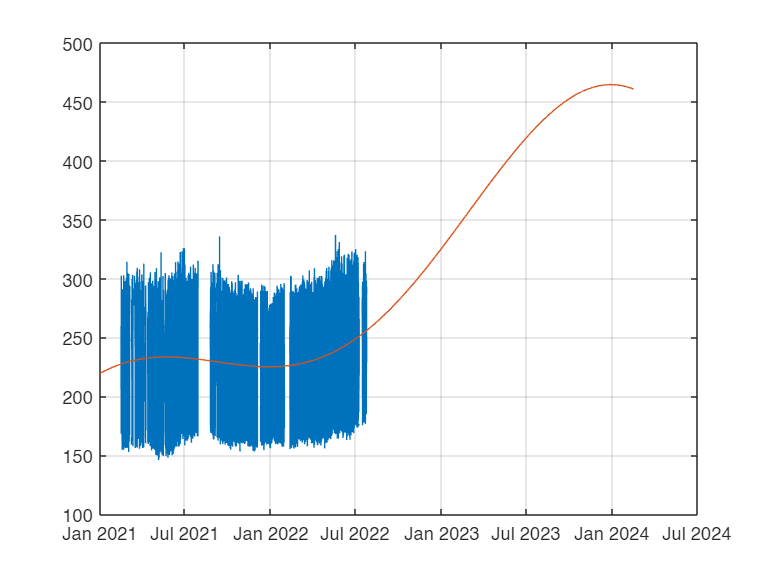

A0 = [ones(length(K2),1) cos((1:FourierTerms)'*w*(K2'))' sin((1:FourierTerms)'*w*(K2'))'];
T2 = datetime(2021,01,01,0:(length(K2)-1),0,0)';

f4 = A0*rcoef;

figure
plot(T,SQ)
hold on
plot(T2,f4)
grid on


figure
plot(SQ./f4)

Arrays have incompatible sizes for this operation.

Related documentation

MeanValue = nanmean(SQ./f4)
grid on

FourierTerms = 100;
w = 2 * pi/(24*7);
KDW = K(incl);
FDW = SQ(incl);
A0 = [ones(length(K),1) cos((1:FourierTerms)'*w*(K'))' sin((1:FourierTerms)'*w*(K'))'];

A1 = [ones(length(KDW),1) cos((1:FourierTerms)'*w*(KDW'))' sin((1:FourierTerms)'*w*(KDW'))'];
rcoef = A1\FDW

rcoef =   232.1081
    1.0042
    2.3201
   -1.3208
    0.6619
   -0.3125
   -0.4564
  -34.1668
    0.3852
   -0.0232


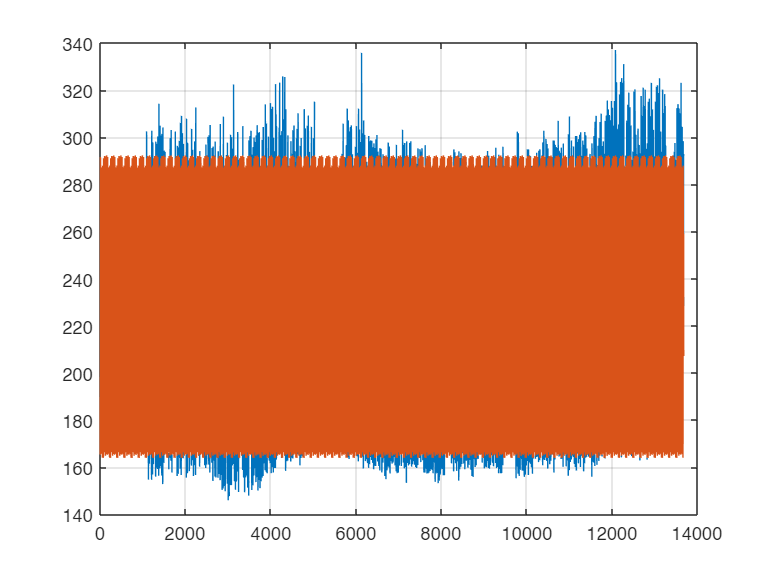


f4 = A0*rcoef;

figure
plot(SQ)
hold on
plot(f4)
grid on

Forecast next week

KF = (13681:(13681+24*7))'

KF =        13681
       13682
       13683
       13684
       13685
       13686
       13687
       13688
       13689
       13690


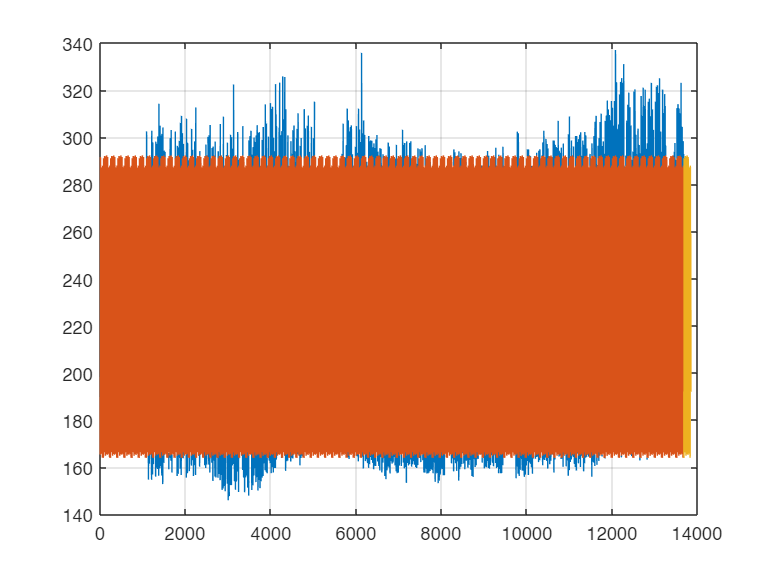

A2 = [ones(length(KF),1) cos((1:FourierTerms)'*w*(KF'))' sin((1:FourierTerms)'*w*(KF'))'];
% forecast 
f5 = A2*rcoef;

hold on
plot(KF,f5)
grid on